plot(GREENvoltage,GREENcurrent,'.')
hold on,


%%CREATING ERRORBARS
xneg=0.001.*[1 1 1 1 1 1];
xpos=xneg;
yneg=(0.2e-12).*[1 1 1 1 1 1];
ypos=yneg;
errorbar(GREENvoltage,GREENcurrent,yneg,ypos,xneg,xpos,'o')


%%NEGATIVE SIDE FIT
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =      -2.000e-12  (-1.667e-11, 1.267e-11)  (\pm 0.534e-11)
  %     p2 =   2.333e-13  (-3.483e-12, 3.95e-12)   (\pm 1.858e-12)

%Goodness of fit:
 % SSE: 6.667e-27
      %R-square: 0.75
  %Adjusted R-square: 0.5
  %RMSE: 8.165e-14
p1 =      -2e-12

p1 = -2.0000e-12

p2 =   2.333e-13

p2 = 2.3330e-13

f = p1*GREENvoltage + p2

f = 	1.0e+-12 *

    0.1333    0.0333   -0.0667   -0.1667   -0.2667   -0.3667


plot(GREENvoltage,f,'m')


%%POSITIVE SIDE FIT
%Linear model Poly1:
 %    f(x) = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =      -4.000e-12  (-4e-12, -4e-12)  (\pm 0.001E-12)
  %     p4 =       6.000e-13  (6e-13, 6e-13)    (\pm 0.001E-13)

%Goodness of fit:
 % SSE: 5.098e-56
  %R-square: 1
 % Adjusted R-square: 1
  %RMSE: 2.258e-28
   p3 =      -4e-12

p3 = -4.0000e-12

   p4 =       6e-13

p4 = 6.0000e-13

   g = p3*GREENvoltage + p4

g = 	1.0e+-12 *

    0.4000    0.2000         0   -0.2000   -0.4000   -0.6000


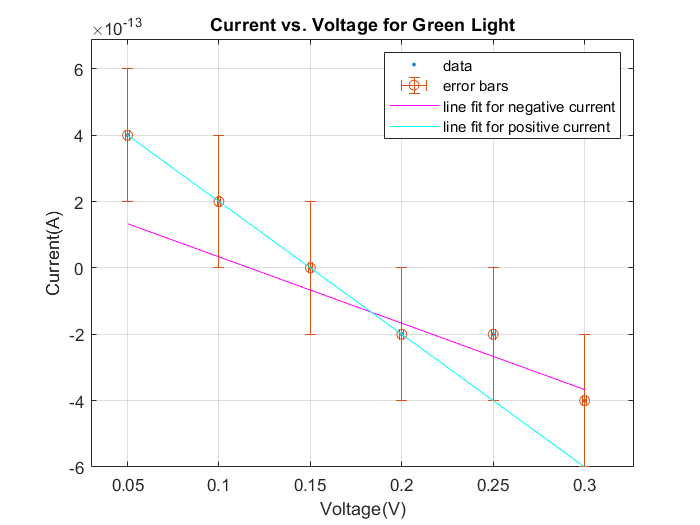

   plot(GREENvoltage,g,'c')
   
   grid on
   title('Current vs. Voltage for Green Light')
xlabel('Voltage(V)')
ylabel('Current(A)')
legend({'data','error bars','line fit for negative current','line fit for positive current'})

xlim([0.030 0.327])
ylim([-0.00000000000060 0.00000000000069])